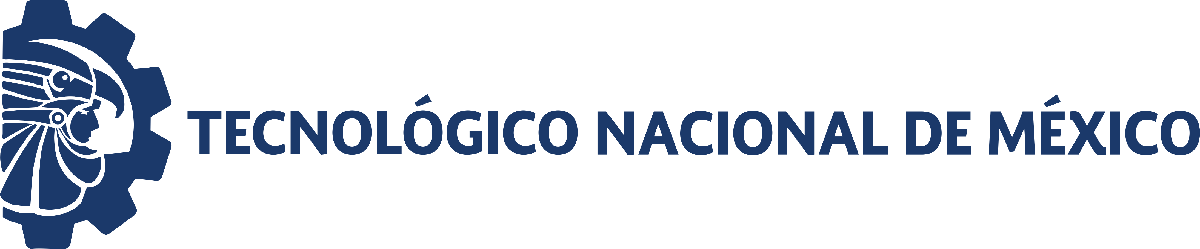                                 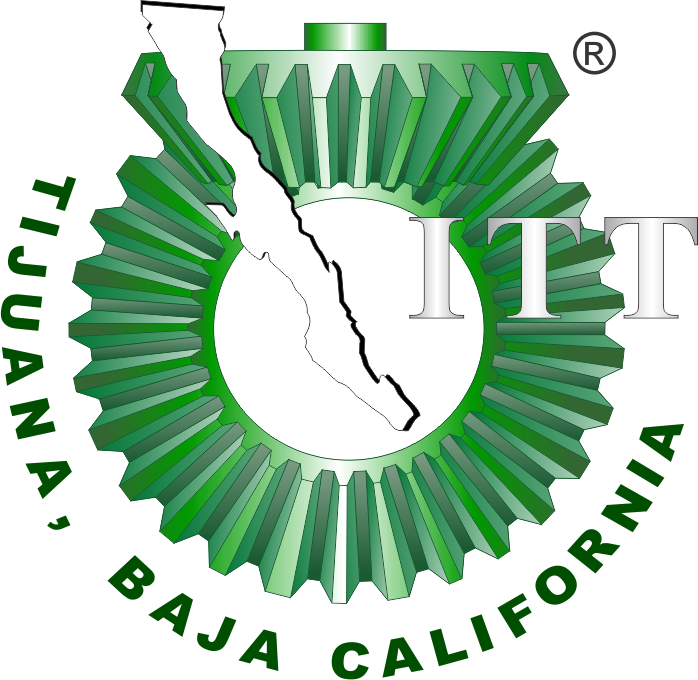

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

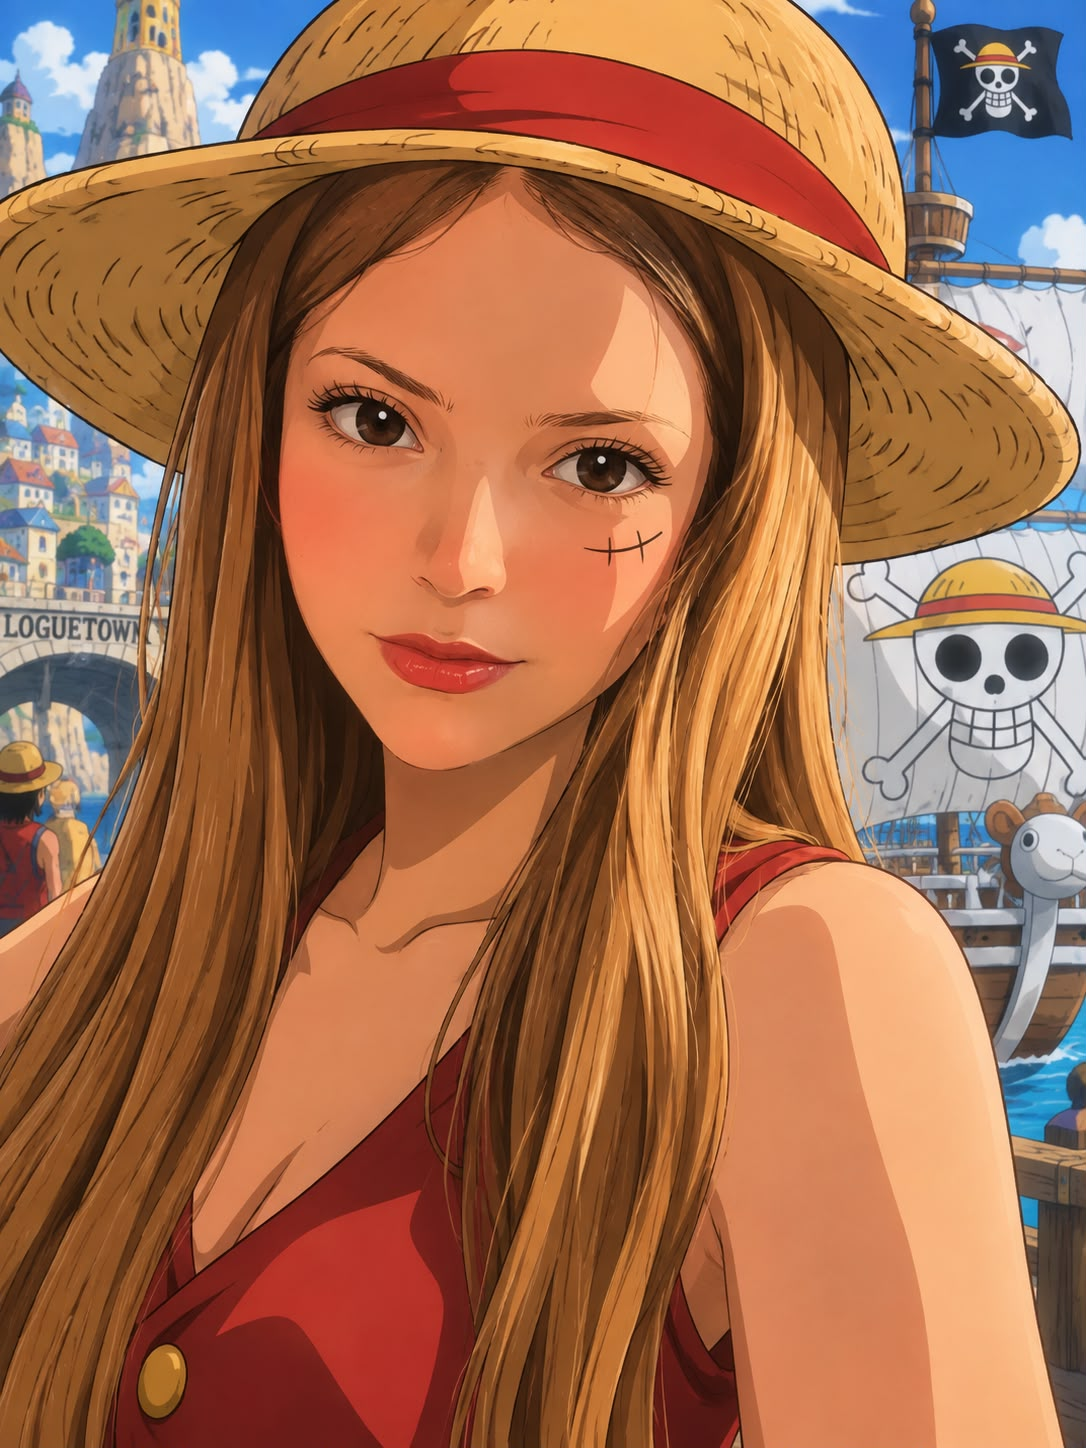

Nombre del alumno: **Ibarra Monroy Ivana Valeria**

Número de control: 23210709

Correo institucional: l23210709**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('ibarra2321070901.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta al escalón

set_param('ibarra2321070901/S1','sw','1')
set_param('ibarra2321070901/Vs(t)','sw','1')

Invalid Simulink object name: 'ibarra2321070901/Vs(t)'.

Caused by:
    Error using Ibarra23210709 (line 7)
    Unable to find block 'Vs(t)'.

x1 = sim('ibarra2321070901', parameters);
plotsignals(x1.t,x1.Vs,x1.Ve,x1.I,'step')

## Respuesta al impulso

set_param('ibarra2321070901/S1','sw','0')
set_param('ibarra2321070901/Vs(t)','sw','1')
x2 = sim('ibarra2321070901', parameters);
plotsignals(x2.t,x2.Vs,x2.Ve,x2.I,'Impulse')

## Respuesta a la rampa

set_param('ibarra2321070901/S1','sw','1')
set_param('ibarra2321070901/Vs(t)','sw','0')
x3 = sim('ibarra2321070901', parameters);
plotsignals(x3.t,x3.Vs,x3.Ve,x3.I,'Ramp')

## Respuesta a la función sinusoidal

set_param('ibarra2321070901/S2','sw','0')
set_param('ibarra2321070901/Vs(t)','sw','0')
x4 = sim('ibarra2321070901', parameters);
plotsignals(x4.t,x4.Vs,x4.Ve,x4.I,'Sinusoidal')

## **Funcion: Respuestas de la simulacion**

function plotsignals(t,Vs,Ve,I,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [9, 21, 64]/255;
clr2 = [118, 146, 255]/255;
clr3 = [171, 210, 250]/255;
order = [clr1;clr2;clr3]; colororder(order)

plot(t,Vs,'-','LineWidth',1.5,'Color',clr1)
plot(t,Ve,'--','LineWidth',1.5,'Color',clr2)
plot(t,I,':','LineWidth',2.5,'Color',clr3)
L = legend ('$V_{s}(t)$','$V_E(t)$','$I(t)$');
set(L,'interpreter','latex','location','northeastoutside',...
   'orientation','vertical')
title(L,[signal,'input'])
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$V_i(t)$ [V],','Interpreter','latex')
xlim([-0.25 10]); xticks(0:1:10)

if signal == "Step"
    ylim([0 1.2]); yticks (0:0.1:1.2)
elseif signal == "Impulse"
    ylim([-0.2 1.2]); yticks (-0.2:0.1:1.2)
elseif signal == "Ramp"
    ylim([-0.1 1.1]); yticks (-0.1:0.1:1.1)
elseif signal == "Sinusoidal"
    ylim([-1.2 1.2]); yticks (-1.2:0.1:1.2)
end

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')



end